R1 = 50;
C1 = 100E-9;
a = R1*C1;

G = tf([1], [a 1])

G =
 
       1
  -----------
  5e-06 s + 1
 
Continuous-time transfer function.




[mag, pha, wout] = bode(G);
fout = wout ./ (2*pi);
f0 = 1/(2*pi*R1*C1)

f0 = 3.1831e+04

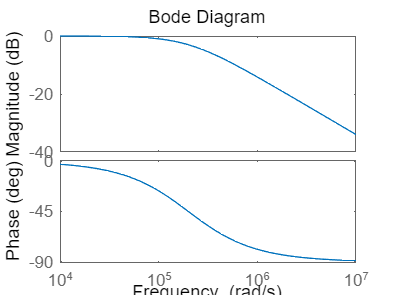

figure
bode(G)

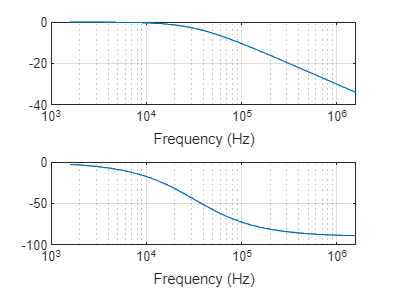

figure
subplot(2,1,1);
semilogx(fout, mag2db(reshape(mag, [1,length(fout)])));
xlabel("Frequency (Hz)")
grid on;
subplot(2,1,2);
semilogx(fout, reshape(pha, [1,length(fout)]));
xlabel("Frequency (Hz)")
grid on